# AAE 421 Final Project MATLAB Code

## Group** 2**

Julia Kozlowski, Nick Gunady, Elio Marcano, Jake Sharbaugh, Jason Thielen, Matt McGuffey, Dylan Pranger, Christian Hallerud, Tomoki Koike, Logan Clark

clear all; close all; clc;

% Define current working directory to make this file adaptable for
% different computers
currentFolder = pwd; 

% Set latex for plot format 
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Add the path for additional function files and simulink files
addpath(genpath(currentFolder + "\funcs"));
addpath(genpath(currentFolder + "\simulink"));

#### Setup

A Lighter-than-air-robot (blimp) is controlled by two sets of propellers with two different axes of rotation. This allows to control the blimp in the longitudinal and lateral direction.

**>> Longitudinal **

The longitudinal dynamics system can be linearized with an alittude of 1 meter, and it can be represented by the following transfer function.


$$\frac{y_a \left(s\right)}{u_a \left(s\right)}=G_a \left(s\right)=\frac{2\ldotp 423s+0\ldotp 1097}{s^3 +0\ldotp 3537s^2 +0\ldotp 1394s+0\ldotp 002024}$$


The state space realization of this system becomes 


$$A_a =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-0\ldotp 002024 & -0\ldotp 1394 & -0\ldotp 3537
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;B_a =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \;$$



$$C_a =\left\lbrack \begin{array}{ccc}
0\ldotp 1097 & 2\ldotp 423 & 0
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;D_a =0$$


The input $u_a$ is the command input to the acuators from the Pulse Width Modulation (PWM) and has a input range of 0 to 255. The output $y_a$ is indicates the altitude of the blimp in the units of mm.

**>> Lateral (Rotational)**

The lateral dynamics involve the following 2 modes: rotational motion and forward motion. The rotational dynamics system is linearized with an equilibrium point of constant heading angle of 0 degrees. For this system, the input $u_h \;$is the PWM input for the acuators with a range of -255 to 255. A negative input specifies the use of the left motor and the positive specifies the right motor. The output $y_h$ is the heading angle of the blimp with the unit of radian. The transfer function that represents this system is as follows.


$$\frac{y_h \left(s\right)}{u_h \left(s\right)}=G_h \left(s\right)=\frac{0\ldotp 00835s+0\ldotp 001745}{s^2 +4\ldotp 641\times {10}^{-5} s+0\ldotp 0002839}$$


The state space realization of this system becomes 


$$A_h =\left\lbrack \begin{array}{cc}
0 & 1\\
-0\ldotp 0002839 & -4\ldotp 641\times {10}^{-5} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;B_h =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \;$$



$$C_h =\left\lbrack \begin{array}{cc}
0\ldotp 001745 & 0\ldotp 00835
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;D_h =0$$


**>> Lateral (Forward)**

The forward mode dynamics is linearized with respect to the equilibrium point of constant forward speed of 0.3 m/s. The input, $u_f$ is a PWM command into the actuator with a range of 0 to 255. The system output, $y_f$ is the forward speed of the blimp with a unit of meters per second. The linearized model is represented by the following transfer function.


$$\frac{y_f \left(s\right)}{u_f \left(s\right)}=G_f \left(s\right)=\frac{0\ldotp 0002557s^2 -0\ldotp 02031s+0\ldotp 05613}{s^3 +0\ldotp 4456s^2 +27\ldotp 55s+4\ldotp 316}$$


The state space realization of this system is


$$A_f =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-4\ldotp 316 & -27\ldotp 55 & -0\ldotp 4456
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;B_f =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \;$$



$$C_f =\left\lbrack \begin{array}{ccc}
0\ldotp 05613 & -0\ldotp 02031 & 0\ldotp 0002557
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;D_f =0$$


Keep in mind that these models are** linearized** models and the transfer functions respresent the open-loop transfer functions with respect to a certain equilibrium point.

#### (a) Compute the Transient Response Properties 

Find the overshoot, settling time, and steady state error of the open loop system of 

**>> Longitudinal **

% Define the system 
num_long = [2.423, 0.1097];                % numerator
den_long = [1, 0.3537, 0.1394, 0.002024];  % denominator
sys_long_ol = tf(num_long, den_long);      % build open loop transfer function 
sys_long_cl = feedback(sys_long_ol, 1);    % unit feedback closed loop TF

**Open Loop**

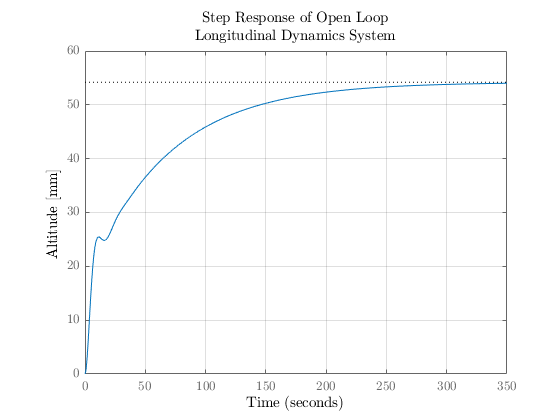

% Plot the step response 
res = stepplot(sys_long_ol);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of Open Loop", "Longitudinal Dynamics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Altitude [mm]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_long_ol);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    ______    ________

     125.93        235.17          48.78         54.078           0            0         54.078     380.24 


**Closed Loop Unit Feedback**

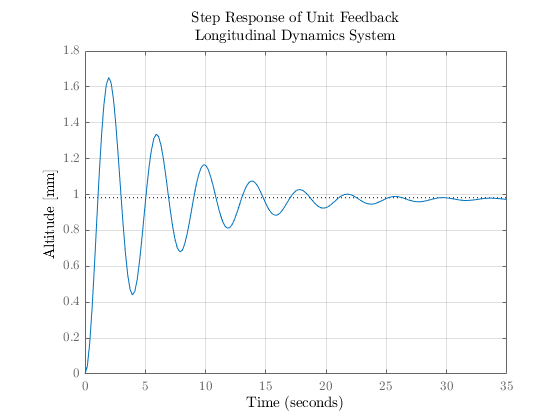

% Plot the step response 
res = stepplot(sys_long_cl);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of Unit Feedback", "Longitudinal Dynamics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Altitude [mm]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_long_cl);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    ______    ________

    0.72117        28.081         0.44062        1.6527         68.32          0         1.6527     1.9678 


The theoretical steady state error for a step response is 


$$e_{\textrm{ss}} =\frac{1}{1+\lim_{s\to 0} G_a \left(s\right)}=\frac{1}{1+\frac{0\ldotp 1097}{0\ldotp 002024}}=0\ldotp 01812\;$$


This is congruent with the results on the plots. (It is the deviation from the value of 1.)

**>> Lateral (Rotational)**

% Define the system 
num_latRot = [0.00835, 0.001745];            % numerator
den_latRot = [1, 4.641e-5, 0.0002839];       % denominator
sys_latRot_ol = tf(num_latRot, den_latRot);  % build open loop transfer function
sys_latRot_cl = feedback(sys_latRot_ol, 1);  % unit feedback closed loop TF

**Open Loop** 

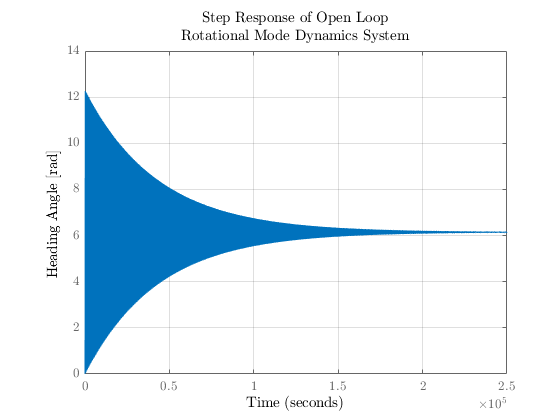

% Plot the step response 
res = stepplot(sys_latRot_ol);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of Open Loop", "Rotational Mode Dynamics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Heading Angle [rad]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_latRot_cl);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot    Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    _____    ________

     23.624        915.88         0.37503         1.512        75.803          0         1.512     62.771 


**Closed Loop Unit Feedback**

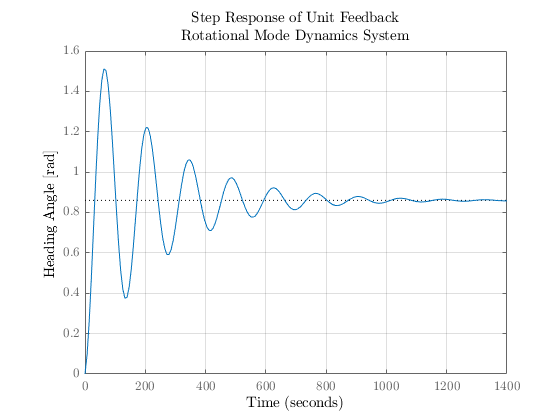

% Plot the step response 
res = stepplot(sys_latRot_cl);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of Unit Feedback", "Rotational Mode Dynamics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Heading Angle [rad]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_latRot_cl);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot    Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    _____    ________

     23.624        915.88         0.37503         1.512        75.803          0         1.512     62.771 


The theoretical steady state error for a step response is 


$$e_{\textrm{ss}} =\frac{1}{1+\lim_{s\to 0} G_h \left(s\right)}=\frac{1}{1+\frac{0\ldotp 001745}{0\ldotp 0002839}}=0\ldotp 1399\;$$


This is congruent with the results on the plots. (It is the deviation from the value of 1.)

**>> Lateral (Forward)**

% Define the system 
num_latFor = [0.0002557, -0.02031, 0.05613];    % numerator
den_latFor = [1, 0.4456, 27.55, 4.316];         % denominator
sys_latFor_ol = tf(num_latFor, den_latFor);     % build open loop transfer function
sys_latFor_cl = feedback(sys_latFor_ol, 1);     % unit feedback closed loop TF

**Open Loop**

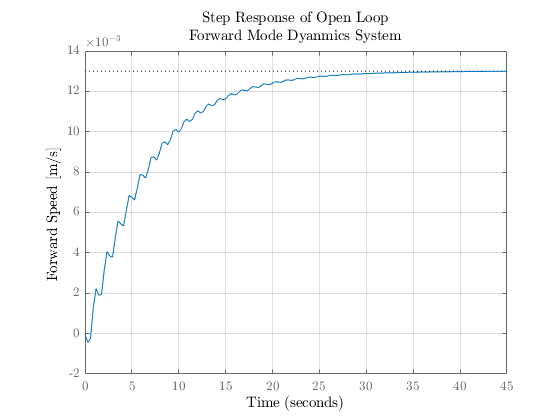

% Plot the step response 
res = stepplot(sys_latFor_ol);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of Open Loop", "Forward Mode Dyanmics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Forward Speed [m/s]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_latFor_cl);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot      Peak      PeakTime
    ________    ____________    ___________    ___________    _________    __________    ________    ________

     14.197        24.778         0.01171       0.012829          0          3.3415      0.012829     45.45  


**Closed Loop Unit Feedback**

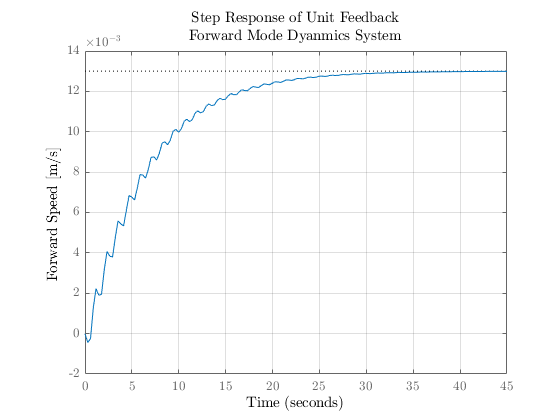

% Plot the step response 
res = stepplot(sys_latFor_ol);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of Unit Feedback", "Forward Mode Dyanmics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Forward Speed [m/s]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_latFor_cl);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot      Peak      PeakTime
    ________    ____________    ___________    ___________    _________    __________    ________    ________

     14.197        24.778         0.01171       0.012829          0          3.3415      0.012829     45.45  


The theoretical steady state error for a step response is 


$$e_{\textrm{ss}} =\frac{1}{1+\lim_{s\to 0} G_f \left(s\right)}=\frac{1}{1+\frac{0\ldotp 05613}{4\ldotp 316}}=0\ldotp 9872$$


This is congruent with the results on the plots. (It is the deviation from the value of 1.)

**REMINDER: Keep in mind that the y-axis is **[m/s]** and not **[mm/s]** that is why there is a 10^(-3) magnitude difference.

#### (b) Root Locus

**>> Longitudinal **

$$Re = 0.1097\,k=0.3537\,w^{2}-0.0020$$

$$Im = 2.4230\,k\,w=w^{3}-0.1394\,w$$

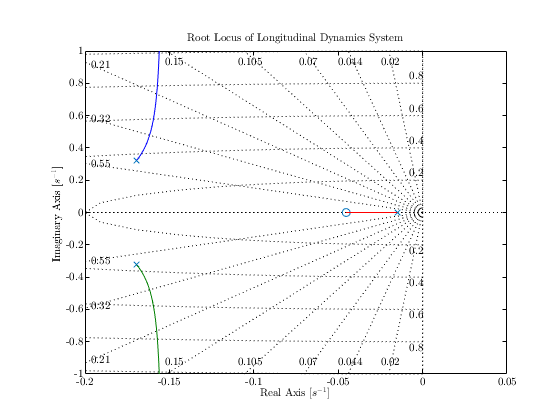

title_string = 'Root Locus of Longitudinal Dynamics System';
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig] = ( ...
    rootLocus_stepBystep_negFeedback(num_long,den_long, title_string));

This gives us the following characteristics of the Root Locus

Poles and Zeros:


$$\textrm{poles}\;\;\Rightarrow \;\;p_1 =-0\ldotp 1693+0\ldotp 3250j,\;\;p_2 =-0\ldotp 1693-0\ldotp 3250j,\;\;p_3 =-0\ldotp 0151\;\;\to \;\;n=3$$



$$\textrm{zeros}\;\;\Rightarrow z_1 =-0\ldotp 0453\;\to \;m=1$$


There are 3 branches and 2 go to $\infty$.

Asymptotes:


$$\theta_a =\frac{180°+360°l}{n-m}=\frac{180°+360°l}{2}=90°+180°l\ \ \ \ where\ l\ =\ 0,\ 1$$



$$\Rightarrow \theta_a =90°,\;\;270°\ \ldotp$$


and the asymptotes intersect with the real axis at 


$$\sigma_a =\frac{\sum p_i -\sum z_i }{n-m}=\frac{\left(-0\ldotp 1693+0\ldotp 3250j\right)+\left(-0\ldotp 1693-0\ldotp 3250j\right)-0\ldotp 0151+0\ldotp 0453}{2}=-0\ldotp 1542$$


Break-in/away Points:


$$\frac{d}{ds}{\left(-\frac{1}{G_a {\left(s\right)}}\right)}=-\frac{d}{ds}{\left(\frac{s^3 +0\ldotp 3537s^2 +0\ldotp 1394s+0\ldotp 002024}{2\ldotp 423s+0\ldotp 1097}\right)}=0$$


Solving this equation, we obtain


$$s=-0\ldotp 2165$$


Since this point is not in the range of 


$$s\in \left\lbrack -0\ldotp 0453,\;-0\ldotp 0151\right\rbrack$$


this point is NOT a break-in/away point.

Angle of Departure:

The departure angle, $\theta_d \;$can be computed for each pole and zero as follows.


$$\theta_d \left(p_1 \right)=180°-arg{\left(G_a {\left(p_1 \right)}\right)}=85\ldotp 5012°$$



$$\theta_d \left(p_2 \right)=180°-arg{\left(G_a {\left(p_2 \right)}\right)}=274\ldotp 4988°$$



$$\theta_d \left(p_3 \right)=180°-arg{\left(G_a {\left(p_3 \right)}\right)}=180°$$



$$\theta_d \left(z_1 \right)=-180°-arg{\left(G_a {\left(z_1 \right)}\right)}=0°$$


Intersection of RL with the Imaginary Axis:

The intersection of the RL with the imaginary axis is a pure complex value. Thus we can obtain the point of intersection by calculating the following equation


$$1+\hat{k} G_a {\left(j\omega^ˆ \right)}=0\ \ \$$


which gives us


$$\textrm{Real}:\;\;0\ldotp 1097\hat{k} =0\ldotp 3537{\hat{w} }^2 -0\ldotp 0020$$



$$\textrm{Imag}:\;2\ldotp 4230\hat{k} \hat{w} ={\hat{w} }^3 -0\ldotp 1394\hat{w} \;\;$$


Solving this non-linear system equation, we obtain the values 


$$\hat{k} =\left\lbrack \begin{array}{c}
-0\ldotp 0185\\
-0\ldotp 0633\\
-0\ldotp 0633
\end{array}\right\rbrack ,\;\hat{w} =\left\lbrack \begin{array}{c}
0\\
-0\ldotp 1179j\\
0\ldotp 1179j
\end{array}\right\rbrack \;\ldotp$$


The $\hat{w}$ values are 0 or imaginary, and therefore, there is NO intersection. 

$\to$with all this information we are able to sketch the Root Locus of this system.

**>> Lateral (Rotational)**

$$Re = 0.0017\,k=w^{2}-2.8390e-04$$

$$Im = 0.0083\,k\,w=-4.6410e-05\,w$$

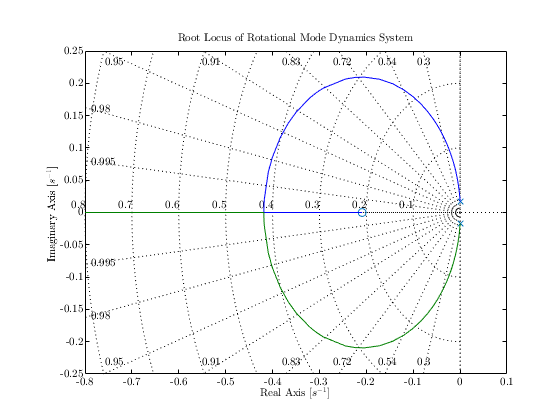

title_string = 'Root Locus of Rotational Mode Dynamics System';
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig] = ( ...
    rootLocus_stepBystep_negFeedback(num_latRot,den_latRot, title_string));

This gives us the following characteristics of the Root Locus

Poles and Zeros:


$$\textrm{poles}\;\;\Rightarrow \;\;p_1 =0\ldotp 0168j,\;\;p_2 =-0\ldotp 0168j\;\;\to \;\;n=2$$



$$\textrm{zeros}\;\;\Rightarrow z_1 =-0\ldotp 2090\;\to \;m=1$$


There are 2 branches and 1 goes to $\infty$.

Asymptotes:


$$\theta_a =\frac{180°+360°l}{n-m}=\frac{180°+360°l}{1}=180°+360°l\ \ \ \ where\ l\ =\ 0$$



$$\Rightarrow \theta_a =180°\ \ldotp$$


No asymptote.

Break-in/away Points:


$$\frac{d}{ds}{\left(-\frac{1}{G_h {\left(s\right)}}\right)}=-\frac{d}{ds}{\left(\frac{s^2 +4\ldotp 641\times {10}^{-5} s+0\ldotp 0002839}{0\ldotp 00835s+0\ldotp 001745}\right)}=0$$


Solving this equation, we obtain


$$s=-0\ldotp 4186,\;0\ldotp 0007$$


The point in the range of 


$$s\in \left\lbrack -\infty ,-0\ldotp 2090\right\rbrack$$


is $s=-0\ldotp 4186$

Thus, this point is the break-in/away point

Angle of Departure:

The departure angle, $\theta_d \;$can be computed for each pole and zero as follows.


$$\theta_d \left(p_1 \right)=180°-arg{\left(G_h {\left(p_1 \right)}\right)}=94\ldotp 6100°$$



$$\theta_d \left(p_2 \right)=180°-arg{\left(G_h {\left(p_2 \right)}\right)}=265\ldotp 3900°$$



$$\theta_d \left(z_1 \right)=-180°-arg{\left(G_h {\left(z_1 \right)}\right)}=-180°$$


Intersection of RL with the Imaginary Axis:

The intersection of the RL with the imaginary axis is a pure complex value. Thus we can obtain the point of intersection by calculating the following equation


$$1+\hat{k} G_a {\left(j\omega^ˆ \right)}=0\ \ \$$


which gives us


$$\textrm{Real}:\;\;0\ldotp 0017\hat{k} ={\hat{w} }^2 -2\ldotp 8390e-4$$



$$\textrm{Imag}:0\ldotp 0083\hat{k} \hat{w} =-4\ldotp 6410e-5\hat{w} \;\;$$


Solving this non-linear system equation, we obtain the values 


$$\hat{k} =\left\lbrack \begin{array}{c}
-0\ldotp 1627\\
-0\ldotp 0056\\
-0\ldotp 0056
\end{array}\right\rbrack ,\;\hat{w} =\left\lbrack \begin{array}{c}
0\\
-0\ldotp 0166\\
0\ldotp 0166
\end{array}\right\rbrack \;\ldotp$$


All $\hat{k}$ values are negative so there are no intersections.

$\to$with all this information we are able to sketch the Root Locus of this system.

**>> Lateral (Forward)**

$$Re = -k\,\left(2.5570e-04\,w^{2}-0.0561\right)=0.4456\,w^{2}-4.3160$$

$$Im = -0.0203\,k\,w=w^{3}-27.5500\,w$$

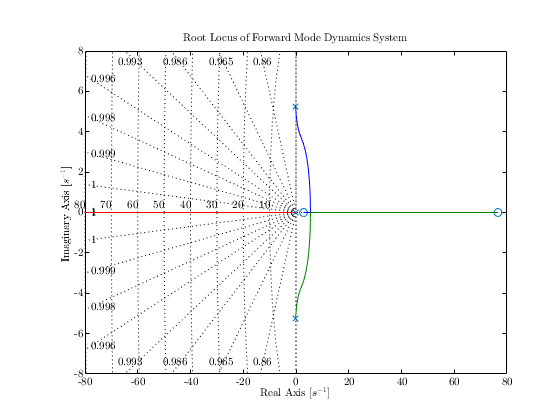

title_string = 'Root Locus of Forward Mode Dynamics System';
[poles,zrs_latFor,angs,sigma,bi_pt,T_P,T_Z,k,w,fig] = ( ...
    rootLocus_stepBystep_negFeedback(num_latFor,den_latFor, title_string));

This gives us the following characteristics of the Root Locus

Poles and Zeros:


$$\textrm{poles}\;\;\Rightarrow \;\;p_1 =-0\ldotp 1443+5\ldotp 2425j,\;\;p_2 =-0\ldotp 1443-5\ldotp 2425j,\;{\;\;p}_3 =-0\ldotp 1569\;\to \;\;n=3$$



$$\textrm{zeros}\;\;\Rightarrow z_1 =76\ldotp 5619,\;\;\;z_2 =2\ldotp 8672\to \;m=2$$


There are 3 branches and 1 goes to $\infty$.

Asymptotes:


$$\theta_a =\frac{180°+360°l}{n-m}=\frac{180°+360°l}{1}=180°+360°l\ \ \ \ where\ l\ =\ 0$$



$$\Rightarrow \theta_a =180°\ \ldotp$$


No asymptote

Break-in/away Points:


$$\frac{d}{ds}{\left(-\frac{1}{G_f {\left(s\right)}}\right)}=-\frac{d}{ds}{\left(\frac{s^3 +0\ldotp 4456s^2 +27\ldotp 55s+4\ldotp 316}{\;\;0\ldotp 0002557s^2 -0\ldotp 02031s+0\ldotp 05613}\right)}=0$$


Solving this equation, we obtain


$$s=155\ldotp 0061,\;5\ldotp 4887$$


The point in the range of 


$$s\in \left\lbrack -\infty ,-0\ldotp 1569\right\rbrack \bigcap \left\lbrack 2\ldotp 8672,76\ldotp 5619\right\rbrack$$


is $s=5\ldotp 4887$

Thus, this point is the break-in/away point

Angle of Departure:

The departure angle, $\theta_d \;$can be computed for each pole and zero as follows.


$$\theta_d \left(p_1 \right)=180°-arg{\left(G_f {\left(p_1 \right)}\right)}=296\ldotp 1024°$$



$$\theta_d \left(p_2 \right)=180°-arg{\left(G_f {\left(p_2 \right)}\right)}=63\ldotp 8976°$$



$$\theta_d \left(p_3 \right)=180°-arg{\left(G_f {\left(p_3 \right)}\right)}=540°=180°$$



$$\theta_d \left(z_1 \right)=-180°-arg{\left(G_f {\left(z_1 \right)}\right)}=-180°$$



$$\theta_d \left(z_2 \right)=-180°-arg{\left(G_f {\left(z_2 \right)}\right)}=0°$$


Intersection of RL with the Imaginary Axis:

The intersection of the RL with the imaginary axis is a pure complex value. Thus we can obtain the point of intersection by calculating the following equation


$$1+\hat{k} G_a {\left(j\omega^ˆ \right)}=0\ \ \$$


which gives us


$$\textrm{Real}:\;-\hat{k} \left(2\ldotp 5570e-4{\hat{w} }^2 -0\ldotp 0561\right)={0\ldotp 4456\hat{w} }^2 -4\ldotp 3160$$



$$\textrm{Imag}:-0\ldotp 00203\hat{k} \hat{w} ={\hat{w} }^3 -27\ldotp 5500\hat{w} \;\;$$


Solving this non-linear system equation, we obtain the values 


$$\hat{k} =\left\lbrack \begin{array}{c}
-0\ldotp 0077\\
0\ldotp 0135\\
0\ldotp 0135\\
-1\ldotp 1330\\
-1\ldotp 1330
\end{array}\right\rbrack \times {10}^4 ,\;\;\;\hat{w} =\left\lbrack \begin{array}{c}
0\\
-4\ldotp 9802\\
4\ldotp 9802\\
-16\ldotp 0517\\
16\ldotp 0517
\end{array}\right\rbrack \;\ldotp$$


The $\hat{w}$ values corresponding to the postive $\hat{k}$values are appropriate.

The intersections are $\pm 4\ldotp 9802$.

$\to$with all this information we are able to sketch the Root Locus of this system.

#### (c) Design Feedback Controllers

For this task a single PID controller is sufficient to control each system.

The requirements to fulfill are 


$$\zeta =0\ldotp 7071$$



$$t_s =2\ldotp 5\;s$$


Which imply 


$$%OS=exp{\left(\frac{-\zeta \pi }{\sqrt{1-\zeta {\;}^2 }}\right)}\times 100\ =\ 4.3217\ %\$$



$$\mathrm{t}\mathrm{i}\mathrm{m}\mathrm{e}\mathrm{\ }\mathrm{c}\mathrm{o}\mathrm{n}\mathrm{s}\mathrm{t}\mathrm{a}\mathrm{n}\mathrm{t}\mathrm{\ }\;≔\mathrm{\ }\;\;\tau \;\;=\frac{t_s }{4.6}\le 2.5\ \ s$$



$$\Rightarrow \tau \le 0.5435\ \ s\ \ \ldotp$$


**>> Longitudinal**

A simulink model "long_with_PID" is created for this task. It is in the "simulink" folder. For this model, the Control System Tuner is used. The model includes a sensor gain and PID controller to satisfy the system requirements.

In the Control System Designer, the PID controller and sensor gain is selected as a block to tune, and the %OS and time constant are used to define a "New Goal" ("Step Tracking Goal").

warning('off');
% Define parameters 
sensor_gain = 1;  % default value of 1

% Open the Control System Tuner 
% controlSystemTuner("long");     % UNCOMMENT IF YOU WANT TO TRY IT YOURSELF!!

From the Control System Tuner we obtain the tuned PID gains as well as the sensor gain.

PID:


$$K_p +K_i \frac{1}{s}+K_d \frac{s}{T_f s+1}$$


   
$$where\ \ \ K_p =-0\ldotp 307,\ \ K_i =1\ldotp 77,\ \ K_d =0\ldotp 784,\ \ T_f =0\ldotp 296$$


Sensor Gain:


$$K_{sensor} =1\ \ \;$$
 

The response looks as follows.

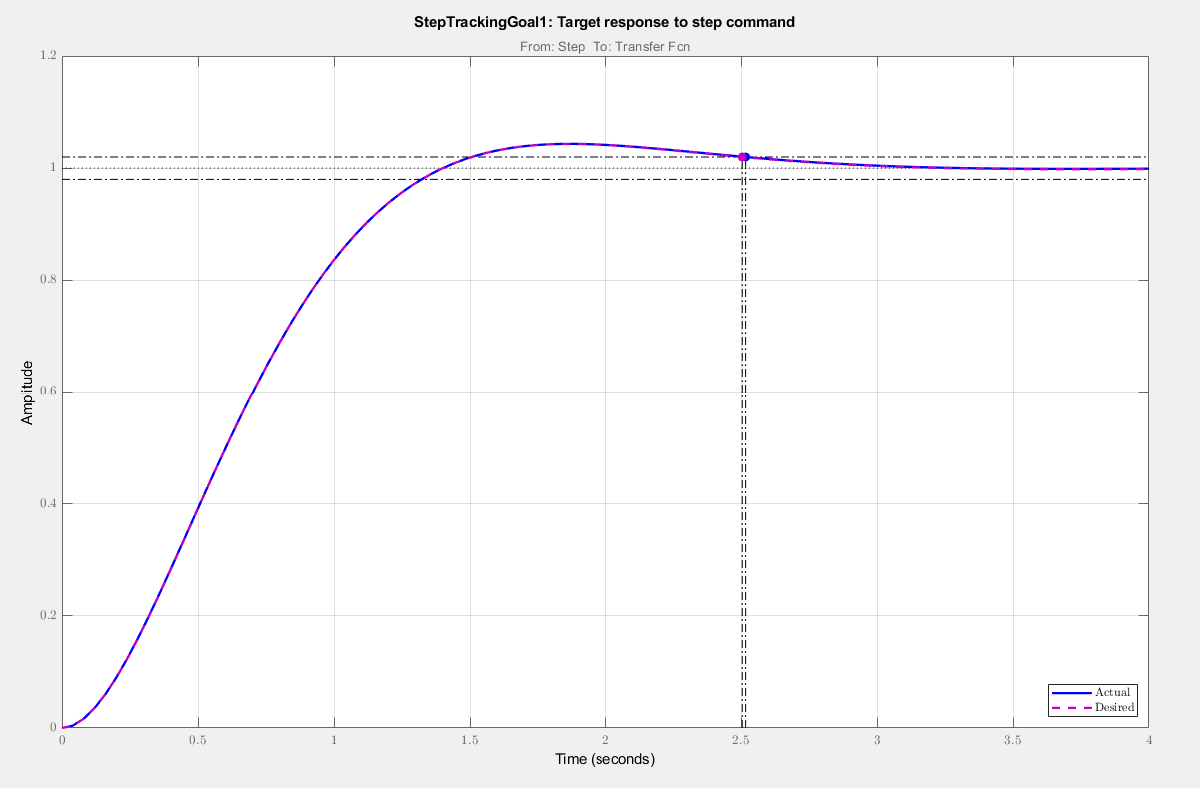        

 For the next step, the transient response properties are computed for this upgraded control system. This is done using the "linmod()" command and linearizing the new system to retrieve the system matrices. (*make sure to replace the "step-input" block with the "in" block.)

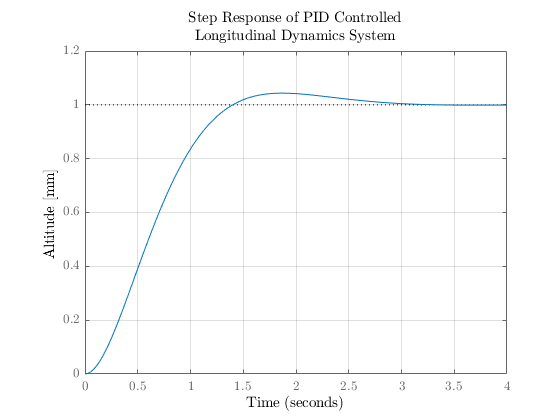

% Linearize and get the system matrices 
[A, B, C, D] = linmod('long');
sys_long_new = ss(A, B, C, D);

% Plot the step response 
res = stepplot(sys_long_new);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of PID Controlled", "Longitudinal Dynamics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Altitude [mm]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_long_new);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    ______    ________

    0.90279        2.517          0.90114        1.0434        4.3373          0         1.0434     1.8798 


**>> Lateral (Rotational)**

From the Root Locus of this system, it is best to implement a cascade control with a controller in the inner loop. Then, a requirement for the inner loop is set as 


$$\zeta_{\textrm{inner}} =0\ldotp 2,\;\;t_{s,\textrm{inner}} =10\ldotp 0$$


This gives 


$$%\textrm{OS}=\;52\ldotp 6620,\;\;\tau \le 2\ldotp 1739$$



$$\omega_n =2\ldotp 3000$$


From these requirements, the desired pole can be computed for the inner loop 


$$s_d =-\zeta \omega_n \pm {j\omega }_n \sqrt{1-\zeta^2 }=-0\ldotp 46\pm 2\ldotp 2535j$$


The angle difficiency of the open loop lateral rotational system for this desired pole is 

sd = -0.46+2.2535*1j;
DA = calc_ang_deficiency(num_latRot, den_latRot, sd);

Since the deficiency angle is negative, it would be best to use a lag compensator in the inner loop.

A simulink model "latRot_with_PID" is created for this task. It is in the "simulink" folder. For this model, the Control System Tuner is used. The model includes a sensor gain and PID controller to satisfy the system requirements.

In the Control System Designer, the PID controller and sensor gain is selected as a block to tune, and the %OS and time constant are used to define a "New Goal" ("Step Tracking Goal").

warning('off');
% Define parameters 
sensor_gain = 1;  % default value of 1

% Open the Control System Tuner 
% controlSystemTuner("latRot");     UNCOMMENT IF YOU WANT TO TRY IT YOURSELF!!

First we tune the inner loop lag compensator to be 


$$K_{\textrm{lag}} =\frac{-6\ldotp 568e-9s+31\ldotp 3}{s+0\ldotp 209}$$


Then the PID controller and sensor gain are tuned for the requirements that we defined for the overall system. And the gains are as follows.

PID:


$$K_p +K_i \frac{1}{s}+K_d \frac{s}{T_f s+1}$$


   
$$where\ \ \ K_p =-0\ldotp 5,\ \ K_i =1\ldotp 69,\ \ K_d =6\ldotp 59,\ \ T_f =0\ldotp 297$$


Sensor Gain:


$$K_{sensor} =\;\textrm{1}\;\;$$
 

The response looks as follows.

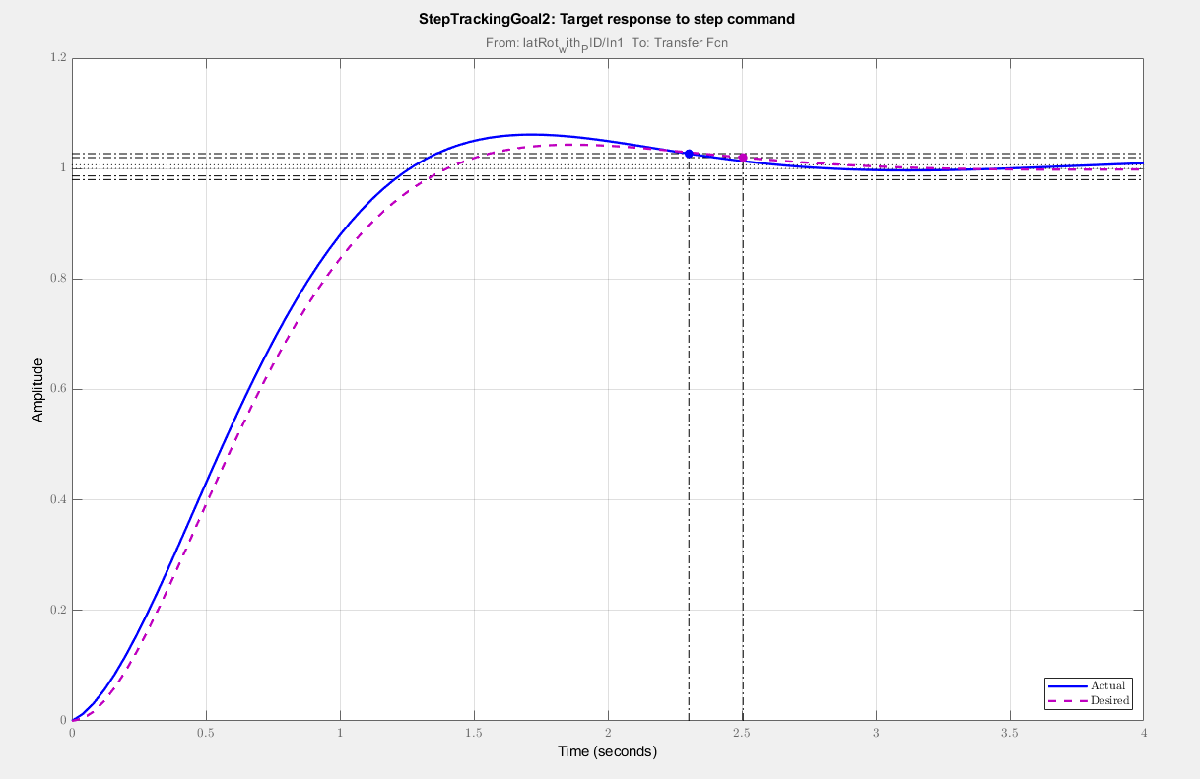

Then, similar to the longitudinal system, the system is linearized and the step response is investigated.

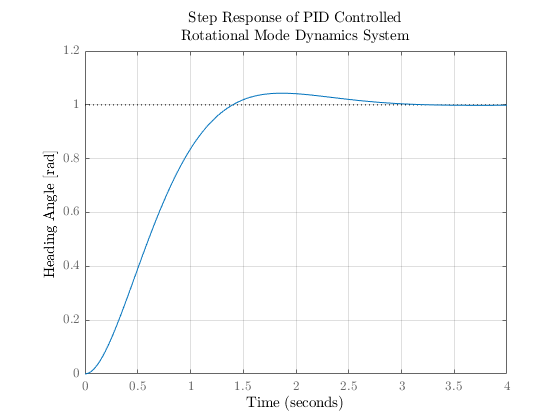

% Linearize and get the system matrices 
[A, B, C, D] = linmod('latRot');
sys_latRot_new = ss(A, B, C, D);

% Plot the step response 
res = stepplot(sys_latRot_new);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of PID Controlled", "Rotational Mode Dynamics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Heading Angle [rad]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_latRot_new);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    ______    ________

    0.90252        2.5044         0.90344        1.0432        4.3213          0         1.0432      1.86  


**>> Lateral (Forward)**

For this system, it is difficult to get a good control with PIDs, so we will use a state estimator and state variable feedback control to control the system.

First we find the state space of the transfer function

[A_latFor, B_latFor, C_latFor, D_latFor] = tf2ss(num_latFor, den_latFor);

The desired poles that satisfy our requirement are 

$\zeta =0\ldotp 7071$ and $\omega_n =2\ldotp 6022$. Thus,


$$s_d =-1\ldotp 8400\pm 1\ldotp 8400j,-2\ldotp 8$$


dp = [-1.84+1.84*1j, -1.84-1.84*1j, -2.8];

Then we find the estimator gain matrix $L$.

% Estimator gain
L = place(A_latFor', C_latFor', dp)';

Then we find the state feedback gain matrix $K$

K = place(A_latFor, B_latFor, dp);

A simulink model "latFor" is created for this task. It is in the "simulink" folder.

% Trim the system for equilibrium points  
IC = [0.3, 0, 0];  % initial conditions

% Linearize the system 
warning('off') 
[An, Bn, Cn, Dn] = linmod('latFor',[0.3,0,0]);
sys_latFor_new = ss(An, Bn, Cn, Dn);

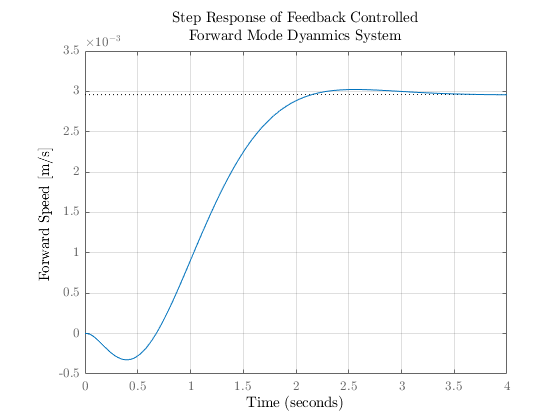

% Plot the step response 
res = stepplot(sys_latFor_new);  % Obtain the step response data 
options = getoptions(res);
options.Title.String = ["Step Response of Feedback Controlled", "Forward Mode Dyanmics System"];
options.Title.Interpreter = "latex";
options.XLabel.Interpreter = "latex";
options.YLabel.String = "Forward Speed [m/s]";
options.YLabel.Interpreter = "latex";
options.Grid = 'on';
setoptions(res, options);


% Acquire the properties 
S = stepinfo(sys_latFor_new);
P = struct2table(S)

P = 1×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot      Peak       PeakTime
    ________    ____________    ___________    ___________    _________    __________    _________    ________

    0.96661        2.0178        0.0026764      0.0030233      2.1182        10.933      0.0030233      2.56  


#### (d) Simulate closed-loop system output trajectory 

#### (i) Track a Circle

First we have to find the constant altitudes and velocity for the blimp 

% Obtain the data
resp1 = sim('trackCirc');
% Extract the required data 
h = resp1.altitude.signals.values;  % altitude
V = resp1.speed.signals.values;  % forward speed 
% Get the average values 
h_avg = mean(h(40000:end));
V_avg = mean(V(20000:end));

The velocity should be constantly 0.3 m/s and the circumference of the circle is $16\pi$. Thus, the time or period of one circle is 


$$\frac{16\pi }{0\ldotp 3}$$


Thus the Hertz of the pulse generation should be 


$$\frac{0\ldotp 3}{16\pi }\;\textrm{Hz}$$


or


$$2\pi \times \left(\frac{0\ldotp 3}{16\pi }\right)\;\frac{\textrm{rad}}{\sec }$$


% Period and time 
P = 16*pi / 0.3;
freq = 1 / P;

% Obtain the angles to track the circle 
resp2 = sim('trackCircle2','TimeOut',P);

% Extract the data
X = resp2.x.signals.values;  % x-positions
Y = resp2.y.signals.values;  % y-positions
HA = resp2.angles.signals.values;  % heading angles
time = resp2.tout;  % time

alt = h_avg*ones(size(time));  % array of altitude 
FS = V_avg*ones(size(time));  % array of foward speed

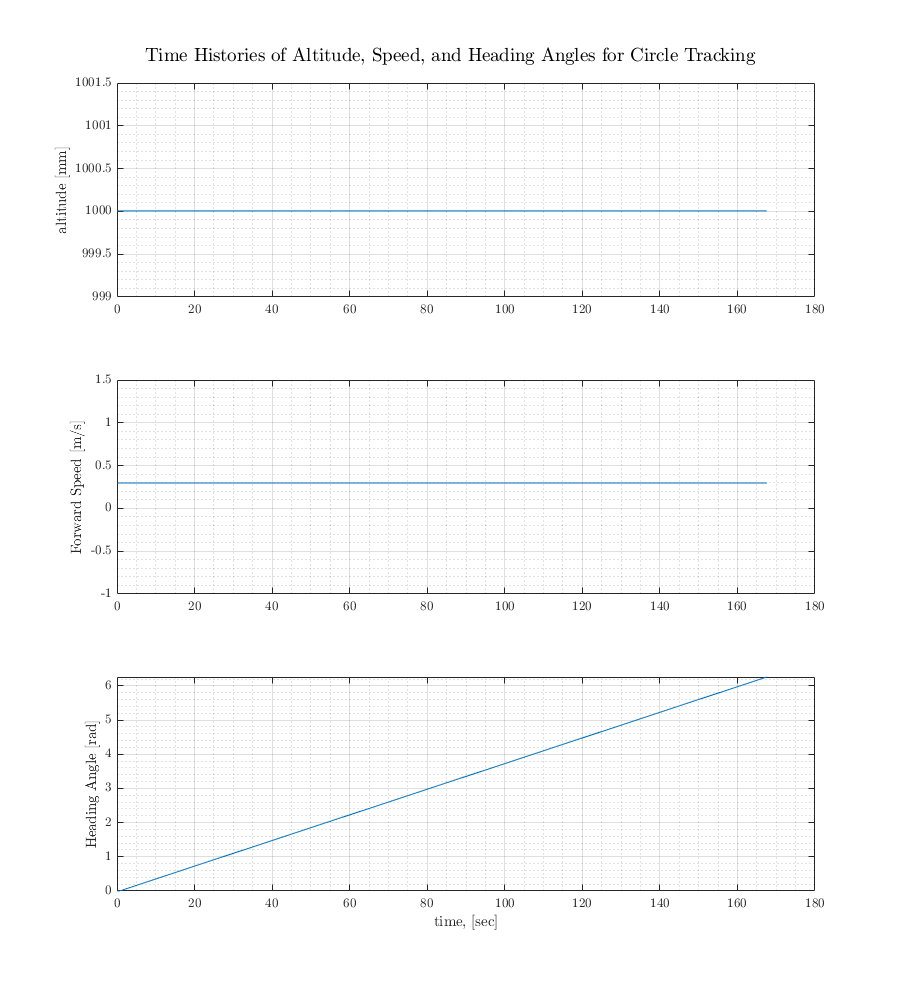

% Plot the altitude, speed, heading angle
fig1 = figure('Renderer',"painters", 'Position', [10 10 900 1000]);
subplot(3,1,1)
plot(time,alt)
grid on; grid minor; box on;
ylabel('altitude [mm]')
subplot(3,1,2)
plot(time,FS)
grid on; grid minor; box on;
ylabel('Forward Speed [m/s]')
subplot(3,1,3)
plot(time,HA)
grid on; grid minor; box on;
ylabel('Heading Angle [rad]')
xlabel('time, [sec]')
sgtitle('Time Histories of Altitude, Speed, and Heading Angles for Circle Tracking')

% Ideal circle
angles = linspace(-pi/2, 3*pi/2, numel(time));
X_ideal = 8*cos(angles); Y_ideal = 8*sin(angles) + 8;
Z_ideal = 1000*ones(size(X_ideal));

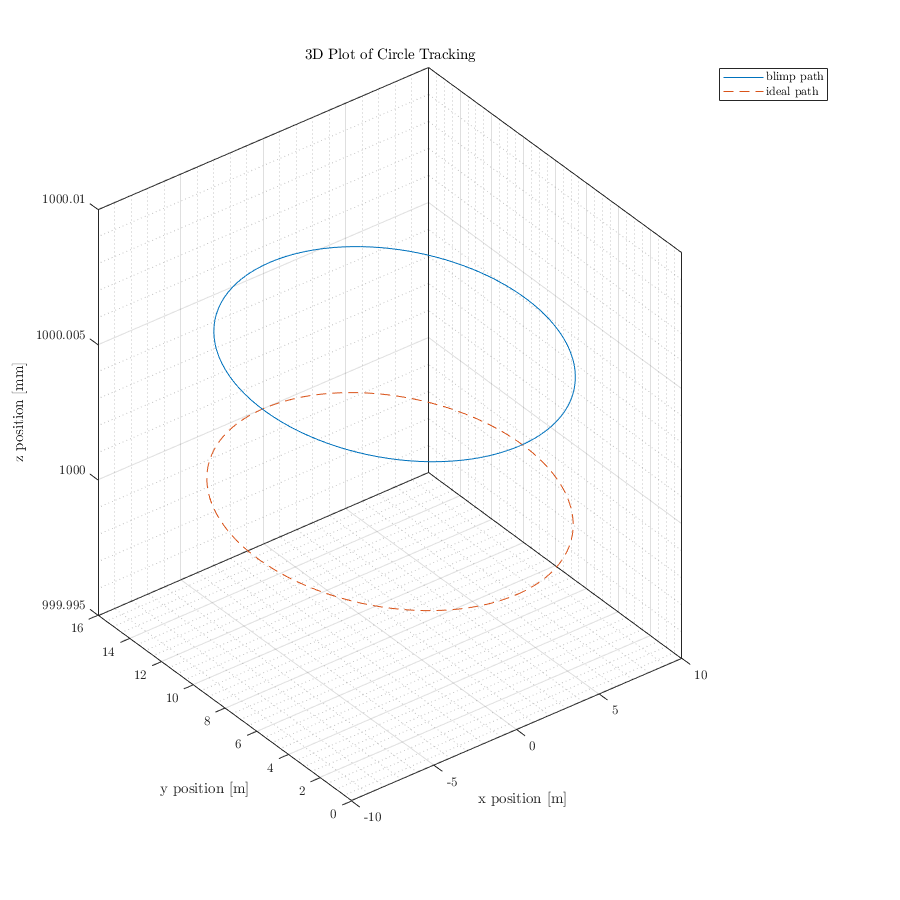

% 3D plot 
fig2 = figure('Renderer', 'painters','Position',[10, 10, 900, 900]);
plot3(X,Y,alt)
hold on; grid on; grid minor; box on;
plot3(X_ideal, Y_ideal, Z_ideal, '--')
hold off
xlabel('x position [m]')
ylabel('y position [m]')
zlabel('z position [mm]')
zlim([999.995, 1000.010])
legend('blimp path', 'ideal path')
title('3D Plot of Circle Tracking')

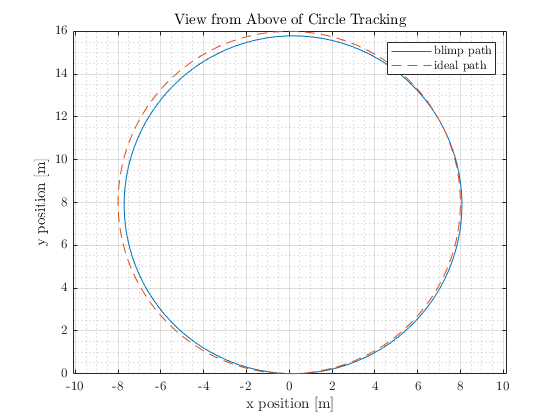

% 2D plot
fig = figure('Renderer', 'painters');
plot(X,Y)
hold on; grid on; grid minor; box on; axis equal;
plot(X_ideal, Y_ideal, '--')
hold off
xlabel('x position [m]')
ylabel('y position [m]')
legend('blimp path', 'ideal path')
title('View from Above of Circle Tracking')

% Calculating the error
% Organize the X and Y data 
organized_angles = -90:0.1:270;
ref = [ones(8,1), zeros(8,1)];
data_angles = [];
for i = 1+7:8:numel(X)
    temp = acosd(dot([X(i-7:i), Y(i-7:i)-8], ref, 2) ./ vecnorm([X(i-7:i), Y(i-7:i)-8],2,2));
    data_angles = [data_angles; temp];
end

idx = find(data_angles == min(data_angles));
data_angles(1:idx) = -data_angles(1:idx);
[minVal, idx2] = min(abs(data_angles - 180));
data_angles(idx2+1:end) = 360 - data_angles(idx2+1:end);

data_angles(2) = -89.999992;
data_angles = sort(data_angles);

[C, ia, ic] = unique(data_angles);
X = X(ia);
Y = Y(ia);
alt = alt(ia);

Xn = interp1(C, X, organized_angles);
Yn = interp1(C, Y, organized_angles);
Zn = interp1(C, alt, organized_angles)/1000;

angles = linspace(-90, 270, numel(Xn));
X_ideal = 8*cosd(angles); Y_ideal = 8*sind(angles) + 8; Z_ideal = ones(size(angles));

X_ideal_n = interp1(angles, X_ideal, organized_angles);
Y_ideal_n = interp1(angles, Y_ideal, organized_angles);
Z_ideal_n = interp1(angles, Z_ideal, organized_angles);

dist_err = [Xn' - X_ideal_n', Yn' - Y_ideal_n', Zn' - Z_ideal_n'];
errors = vecnorm(dist_err, 2, 2);

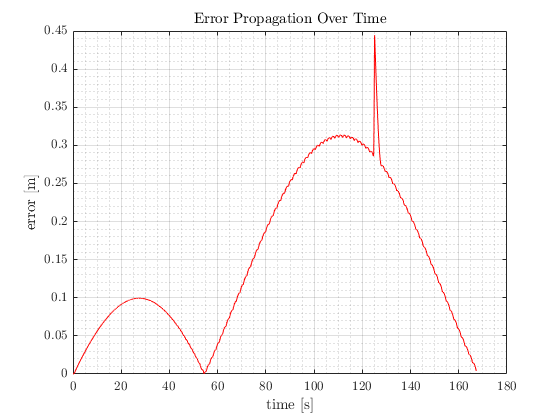

% Plot the error propagation for norm(X,Y,Z) distance error over time
fig = figure("Renderer", 'painters');
plot(linspace(0, time(end), numel(errors)), errors, '-r')
grid on; grid minor; box on;
title('Error Propagation Over Time')
xlabel('time [s]')
ylabel('error [m]')

% Accumulative error
T = linspace(0, time(end), numel(errors));
error_T = interp1(T, errors, 0:round(time(end)));
acc_error = nansum(error_T)

acc_error = 25.3936